# Feedforward neural network architecture search

Data Preparation

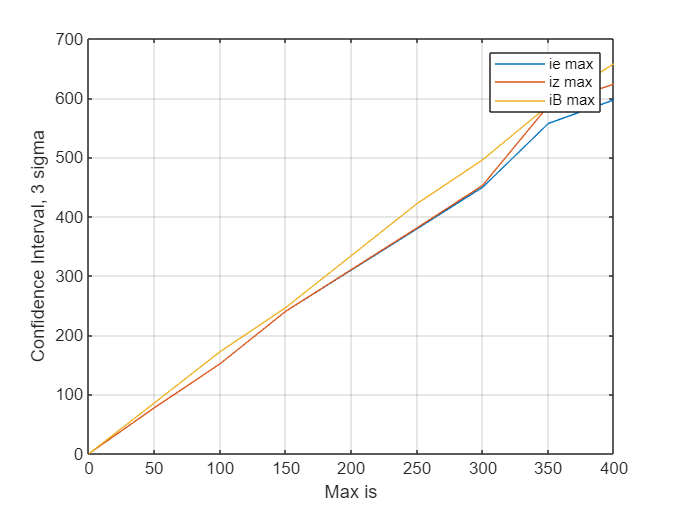

idx = 5

beta =     2.5747
    1.5202


ie_max = 382.6277

ie_max = 379.5059

beta =    -3.3579
    1.5881


iz_max = 393.6622

iz_max = 381.0048

beta =     2.8270
    1.6531


iB_max = 416.1112

iB_max = 421.8935

iy_max = 280

C = 0.0050

vc_mean_ref = 18000

E = 8.9100e+05

VB = 12000

IB = 500

IE = 500

VO = 1000

IS = 250

Xmax = 1.0e+05 *

    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    8.9100
    0.0770


Ymax =          500
         500
         500
         500
        1000


Nbuffer_variables = 27

Nsamples = 10000

Ninputs = 21

Noutputs = 5

ans =           21       10000


ans =            5       10000


Ninputs = 21

Nsamples = 10000

Noutputs = 5

Nsamples = 10000

Nsamples = 10000

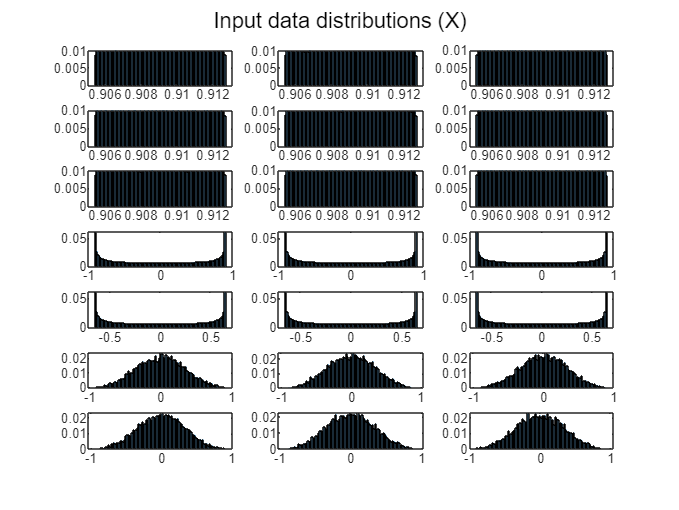

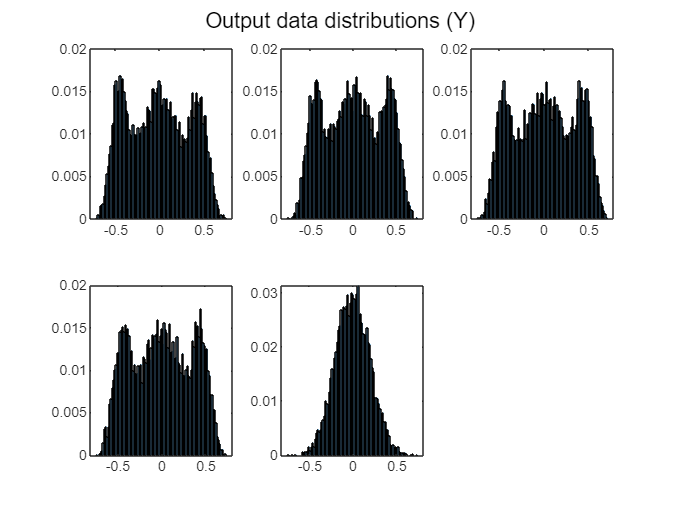

run("DataPreparation.mlx")

PERFORM SEARCH (CAREFUL)

perform_search = true;

Architecture search

Ninputs = 9+6+6

Ninputs = 21

Noutputs = 5;

Nlayers_range = 1:3

Nlayers_range =      1     2     3


Nneurons_range = round(linspace(round(Ninputs/2), 5*Ninputs, 5))

Nneurons_range =     11    35    58    82   105



if perform_search
tic

% Initialize progress bar
h = waitbar(0, 'Performing Architecture Search...');
Narchitectures = length(Nlayers_range) * length(Nneurons_range)
iteration = 1;

% Initialize matrices for results
results = [];

% Iterate over architecture range
for Nlayers = Nlayers_range
    for Nneurons = Nneurons_range
        try
            net_name = [num2str(Nlayers) 'L' num2str(Nneurons) 'N'];
            
            % Architecture
            argsFFNN = struct();
            argsFFNN.Ninputs = Ninputs;
            argsFFNN.Noutputs = Noutputs;
            argsFFNN.Nlayers = Nlayers;
            argsFFNN.Nneurons = Nneurons;
            argsFFNN.hidden_activation = 'relu';
            argsFFNN.output_activation = 'tanh';
            argsFFNN.dropout = 0;
            argsFFNN.WinitFcn = 'glorot';
            argsFFNN.BinitFcn = 'glorot';
            argsFFNN.batchnorm = true;
            argsFFNN.train_bias = true;
            argsFFNN.scaling = false;
            argsFFNN.Xmax = Xmax;
            argsFFNN.Ymax = Ymax;
            
            FFnet = FFNNgenerator(argsFFNN);

            % Training
            argsFFNNtrain = struct();
            argsFFNNtrain.net = FFnet;
            argsFFNNtrain.X_train = dlX_tr;
            argsFFNNtrain.Y_train = dlY_tr;
            argsFFNNtrain.X_val = dlX_val;
            argsFFNNtrain.Y_val = dlY_val;
            argsFFNNtrain.regularization = 0;
            argsFFNNtrain.lr_i = 1e-2;
            argsFFNNtrain.lr_f = 1e-6;
            argsFFNNtrain.plots = 'none';
            argsFFNNtrain.MaxEpochs = 1000;
            argsFFNNtrain.MiniBatchSize = 256;
            argsFFNNtrain.ValidationPatience = 50;
            
            FFnet = FFNNtrain(argsFFNNtrain);

            % Evaluating
            trainPerformance = mse(FFnet.predict(dlX_tr), dlY_tr);
            valPerformance = mse(FFnet.predict(dlX_val), dlY_val);

            % Results
            results(end+1, :) = [Nlayers, Nneurons, trainPerformance, valPerformance];

            % Save net
            save(fullfile('ImitationLearning/ArchitectureSearch/FFNN/Results/Architectures', ['A' net_name '.mat']), 'FFnet');

        catch ME
            disp(['Error ' net_name ': ' ME.message]);
            continue;
        end

        % Update progress bar
        waitbar(iteration/Narchitectures, h, sprintf('Progress: %d%%', round((iteration/Narchitectures)*100)));
        iteration = iteration + 1;

    end
end
toc

% Close progress bar
close(h)

csvwrite('ImitationLearning/ArchitectureSearch/FFNN/Results/Performance/performance.csv', results);

end

Narchitectures = 15

Elapsed time is 1381.835191 seconds.


# Results analysis

## Heatmap

data = readmatrix('ImitationLearning/ArchitectureSearch/FFNN/Results/Performance/performance.csv');
data(:, 5) = data(:, 3)./data(:, 4); % Generalization (MSE_tr/MSE_val)
data(:, 3:5) = data(:, 3:5)*100; % Percentage-like
Narchitectures = size(data, 1)

Narchitectures = 15

Nlayers_range = sort(unique(data(:, 1)))'

Nlayers_range =      1     2     3


Nneurons_range = sort(unique(data(:, 2)))'

Nneurons_range =     11    35    58    82   105


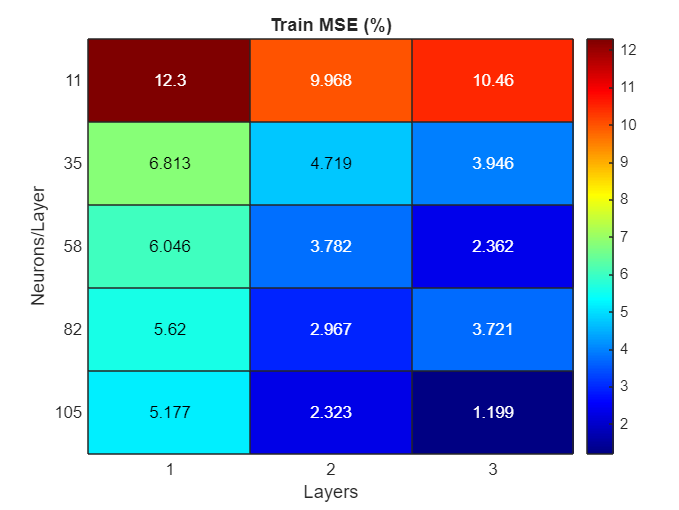


% Performances
trainPerformance = reshape(data(:, 3), [length(Nneurons_range), length(Nlayers_range)]);
valPerformance = reshape(data(:, 4), [length(Nneurons_range), length(Nlayers_range)]);
generalizationPerformance = reshape(data(:, 5), [length(Nneurons_range), length(Nlayers_range)]);

% Training
figure;
heatmap(Nlayers_range, Nneurons_range, round(trainPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('Train MSE (%)');
colorbar;
colormap jet;

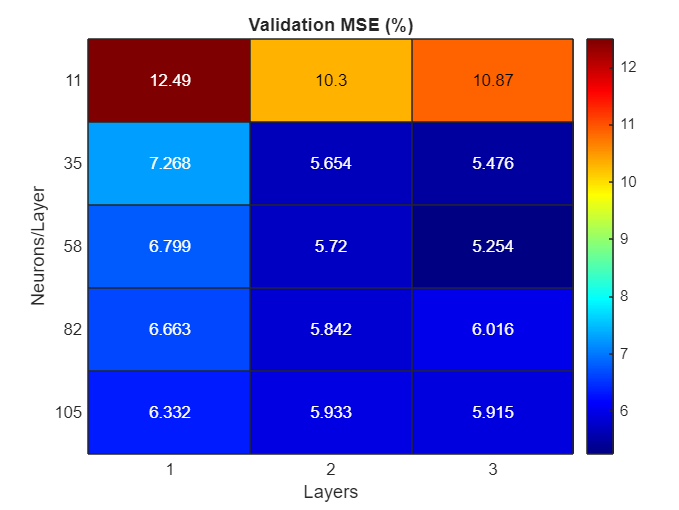


% Validation
figure;
heatmap(Nlayers_range, Nneurons_range, round(valPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('Validation MSE (%)');
colorbar;
colormap jet;

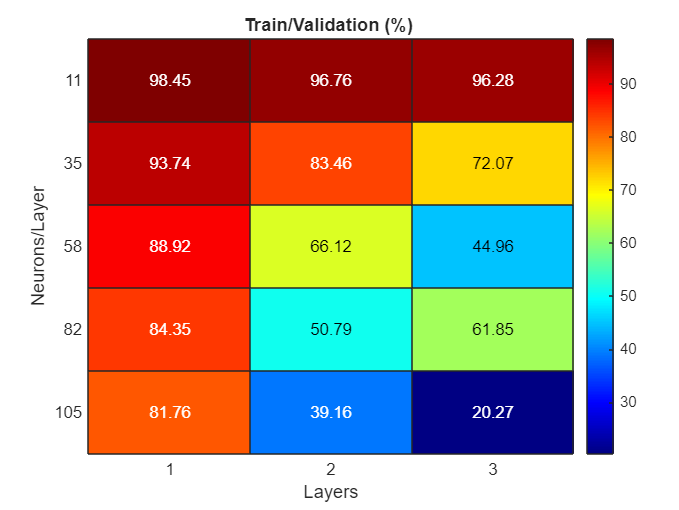


% Generalization
figure;
heatmap(Nlayers_range, Nneurons_range, round(generalizationPerformance, 4));
xlabel('Layers');
ylabel('Neurons/Layer');
title('Train/Validation (%) ');
colorbar;
colormap jet;

## 3d Plot

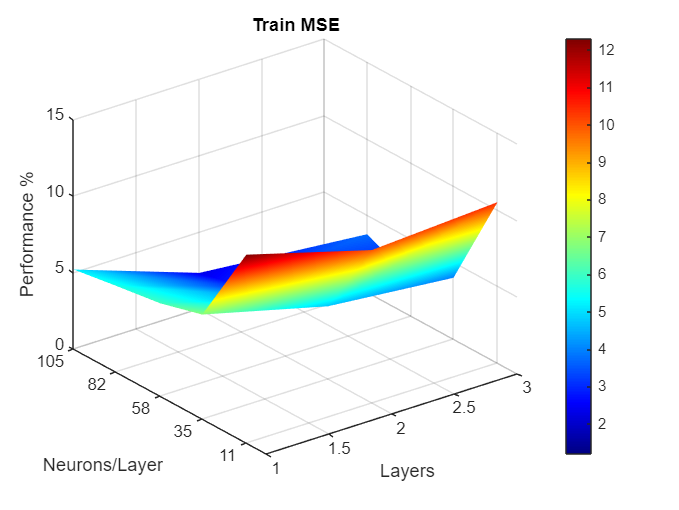

% Training
figure;
surf(Nlayers_range, Nneurons_range, trainPerformance, 'EdgeColor', 'none');
xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Performance %');
title('Train MSE');
colorbar;
colormap jet;
shading interp;

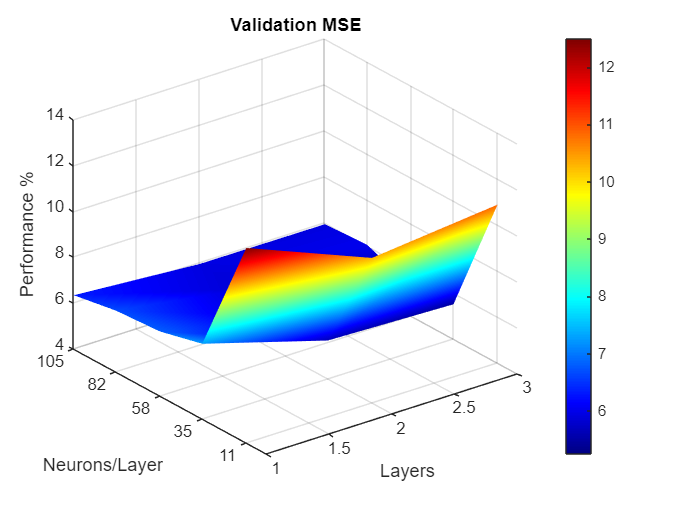


% Validation
figure;
surf(Nlayers_range, Nneurons_range, valPerformance, 'EdgeColor', 'none');
xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Performance %');
title('Validation MSE');
colorbar;
colormap jet;
shading interp;

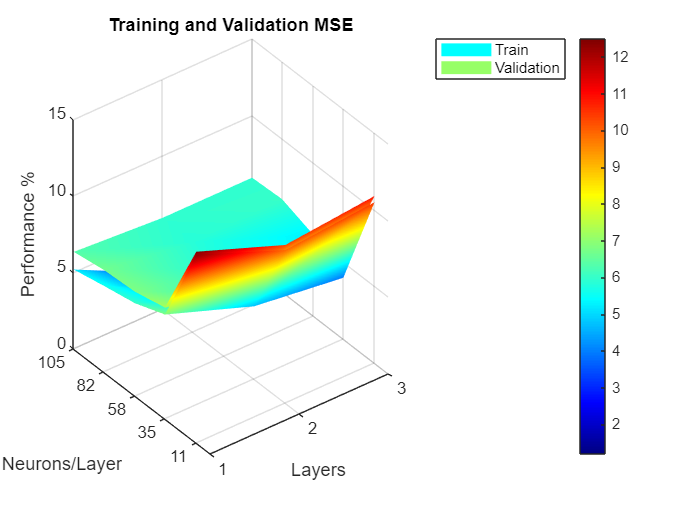


% Training and validation
figure;
surf(Nlayers_range, Nneurons_range, trainPerformance, 'EdgeColor', 'none');
hold on
surf(Nlayers_range, Nneurons_range, valPerformance, 'EdgeColor', 'none');
hold off
xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Performance %');
title('Training and Validation MSE');
legend(["Train", "Validation"])
colorbar;
colormap jet;
shading interp;

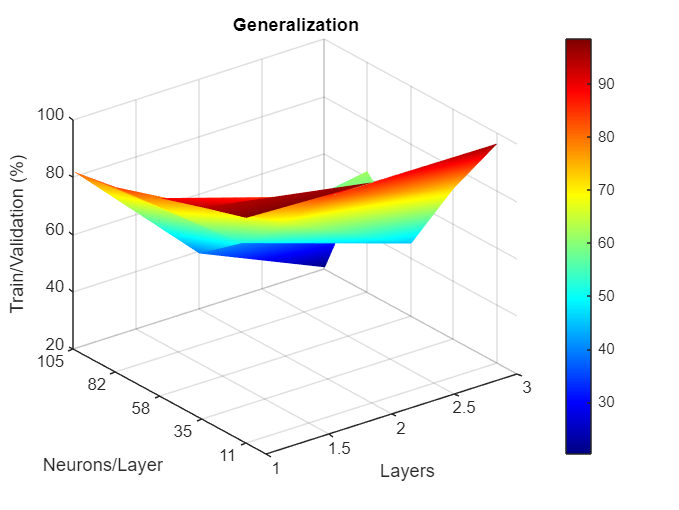


% Generalization
figure;
surf(Nlayers_range, Nneurons_range, generalizationPerformance, 'EdgeColor', 'none');
xlabel('Layers');
ylabel('Neurons/Layer');
yticks(Nneurons_range)
zlabel('Train/Validation (%)');
title("Generalization");
colorbar;
colormap jet;
shading interp;

## Tables

From saved performances

Nbest_architectures = 10;

train_table = sortrows(data, 3);
validation_table = sortrows(data, 4);
diff_table = sortrows(data, 5, 'descend');

train_table = train_table(1:Nbest_architectures, :);
validation_table = validation_table(1:Nbest_architectures, :);
diff_table = diff_table(1:Nbest_architectures, :);

train_table = array2table(train_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Gen'});
validation_table = array2table(validation_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr',  'MSE_val', 'Gen'});
diff_table = array2table(diff_table, 'VariableNames', {'Layers', 'Neurons/Layer', 'MSE_tr', 'MSE_val', 'Gen'});

disp([num2str(Nbest_architectures) ' best training performances']);

10 best training performances


disp(train_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val     Gen  
    ______    _____________    ______    _______    ______
      3            105         1.1992    5.9147     20.275
      2            105         2.3233    5.9328      39.16
      3             58         2.3624     5.254     44.964
      2             82         2.9675    5.8422     50.794
      3             82          3.721    6.0159     61.853
      2             58         3.7817    5.7196     66.118
      3             35         3.9464    5.4756     72.072
      2             35         4.7186     5.654     83.456
      1            105         5.1767    6.3318     81.757
      1             82         5.6201    6.6626     84.353



disp([num2str(Nbest_architectures) ' best validation performances']);

10 best validation performances


disp(validation_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val     Gen  
    ______    _____________    ______    _______    ______
      3             58         2.3624     5.254     44.964
      3             35         3.9464    5.4756     72.072
      2             35         4.7186     5.654     83.456
      2             58         3.7817    5.7196     66.118
      2             82         2.9675    5.8422     50.794
      3            105         1.1992    5.9147     20.275
      2            105         2.3233    5.9328      39.16
      3             82          3.721    6.0159     61.853
      1            105         5.1767    6.3318     81.757
      1             82         5.6201    6.6626     84.353



disp([num2str(Nbest_architectures) ' best generalization performances']);

10 best generalization performances


disp(diff_table);

    Layers    Neurons/Layer    MSE_tr    MSE_val     Gen  
    ______    _____________    ______    _______    ______
      1             11         12.299    12.493     98.447
      2             11         9.9677    10.301     96.764
      3             11         10.463    10.867     96.282
      1             35         6.8133    7.2682     93.741
      1             58         6.0457    6.7992     88.918
      1             82         5.6201    6.6626     84.353
      2             35         4.7186     5.654     83.456
      1            105         5.1767    6.3318     81.757
      3             35         3.9464    5.4756     72.072
      2             58         3.7817    5.7196     66.118
